# Изучение красного смещения звёзд

close all;
clear variables;

## Импорт данных

spectra = importdata("spectra.csv");
lambdaStart = importdata("lambda_start.csv");
lambdaDelta = importdata("lambda_delta.csv");
starNames = importdata("star_names.csv");

## Константы

lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/с

## Определение числа наблюдений

nObs = size(spectra, 1);

## Определение числа иследуемых звёзд

nStars = size(starNames, 1); 

## Определение диапазона длин волн

lambdaEnd = lambdaStart + (nObs -1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

## Расчет скорости удаления звезды от Земли

s = spectra (: , 1:nStars);
[sHa, idx] = min(s);
lambdaHa = lambda(idx);

z = (lambdaHa / lambdaPr) - 1 ;
speed = z * speedOfLight;

## Определение имен удаляющихся звёзд

stand = find(speed<0);
movaway = starNames;
movaway(stand,:) = [];

## Построение графика

fg1 = figure;
hold on;
xlabel('Длина волны, нм');
ylabel(['Интенсивность, эрг/*см^2/с/', char(192)]);
title({'Спектры звезд '});
set(fg1,'Visible','on');
grid on;
for i = 1:nStars
    if abs(speed(i))==speed(i)
        plot(lambda, s(:,i), "-", "LineWidth", 3);
    else
        plot(lambda, s(:,i), "--", "LineWidth", 1);
    end    
end
legend(starNames(1:nStars),'Location',"southwest");
text(lambdaEnd - 20, max(max(s)), ('Бочкарев Фёдор Б01-008'))
hold off;

## Сохранение графика

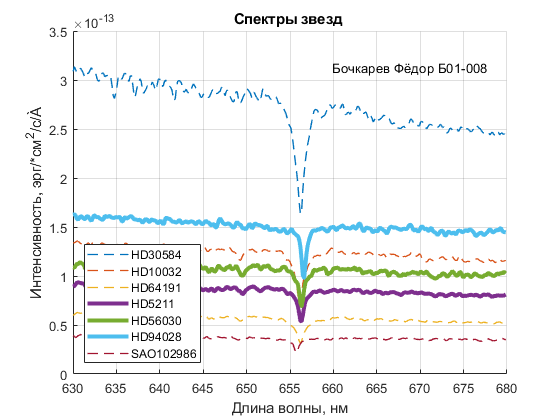

saveas(fg1,'stars_spectra.png');